# Import data from text file

Script for importing data from the following text file:

Auto-generated by MATLAB on 2022-06-06 16:33:57

## Set up the Import Options and import the data

opts = delimitedTextImportOptions("NumVariables", 5);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ["\t", ","];

% Specify column names and types
opts.VariableNames = ["Freq", "abs_Z", "arg_Z"];
opts.VariableTypes = ["double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, ["abs_Z", "arg_Z"], "TrimNonNumeric", true);
opts = setvaropts(opts, ["abs_Z", "arg_Z"], "ThousandsSeparator", ",");

% Import the data
tbl = readtable("AC_Overall.txt", opts);

## Convert to output type

Freq = tbl.Freq;
abs_Z = 10.^(tbl.abs_Z/20);
arg_Z = tbl.arg_Z;

## Clear temporary variables

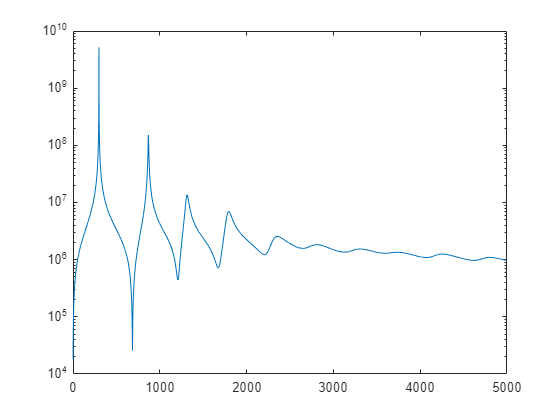

clear opts tbl

semilogy(Freq,abs_Z);

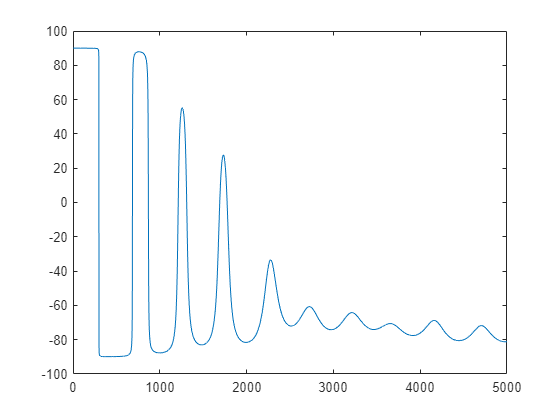

plot(Freq,arg_Z);
hold off

D = [Freq, abs_Z, arg_Z];
save 'AC_Overall_.txt' D -ascii
clear D
